# Compensador de Avanço e de Atraso

## Funções de transferência

clear;
load fts.mat
s = tf('s');

## Gtheta

zpk(G_theta)

ans =
 
            -17.422 s
  -----------------------------
  (s-8.441) (s+4.423) (s+19.21)
 
Continuous-time zero/pole/gain model.
Model Properties


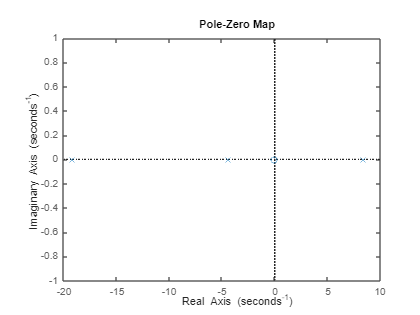

pzplot(G_theta)

### Parâmetros do controlador 

- w_c: frequência de corte desejada para a malha fechada

- sigma: distância entre o zero e o polo do compensador de avanço

Ajuste os parâmetros para melhorar o controlador

w_c = 7*pi, sigma = 6

w_c = 21.9911

sigma = 6

#### Compensador de avanço

z_lead = w_c/sqrt(sigma), p_lead = w_c*sqrt(sigma)

z_lead = 8.9778

p_lead = 53.8671

#### Compensador de atraso

z_lag = 20, p_lag = 0

z_lag = 20

p_lag = 0

### Controlador

C_theta = zpk((s+z_lead)/(s+p_lead) * (s+z_lag)/(s+p_lag))

C_theta =
 
  (s+20) (s+8.978)
  ----------------
    s (s+53.87)
 
Continuous-time zero/pole/gain model.
Model Properties


k_theta = -1/abs(evalfr(-G_theta*C_theta, j*w_c))

k_theta = -72.9757

Gmf_theta = minreal(zpk(feedback(k_theta*C_theta*G_theta,1)))

Gmf_theta =
 
           1271.4 (s+20) (s+8.978)
  -----------------------------------------
  (s+28.3) (s+15.62) (s^2 + 25.14s + 429.1)
 
Continuous-time zero/pole/gain model.
Model Properties


#### Lugar das raizes da planta em malha fechada

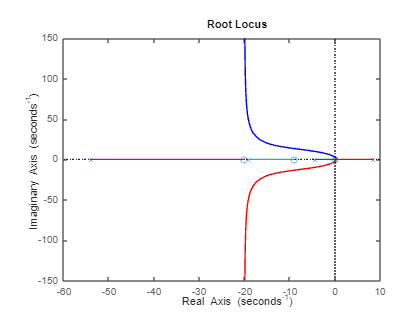

rlocus(-C_theta*G_theta)

### Diagrama de bode da malha fechada

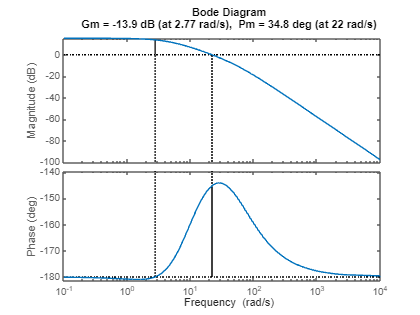

margin(k_theta*C_theta*G_theta)
xlim([1e-1 1e4])

### Resposta ao degrau da planta em malha fechada

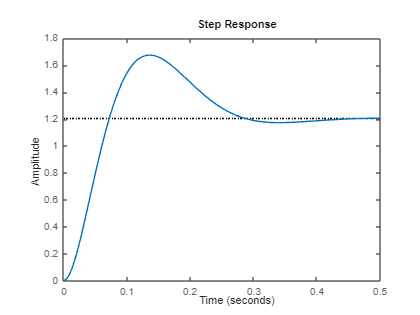

step(Gmf_theta)

## Gphi

zpk(G_phi)

ans =
 
  -2.9209 (s-7.961) (s+7.961)
  ---------------------------
              s^2
 
Continuous-time zero/pole/gain model.
Model Properties


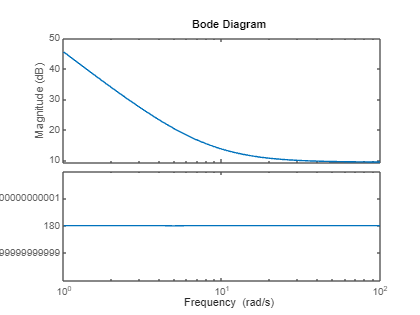

bode(G_phi)

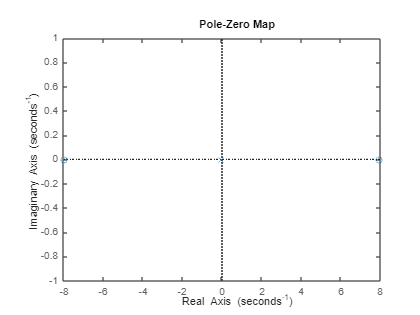

pzplot(G_phi)

### Parâmetro do controlador 

- w_c: frequência de corte desejada para a malha fechada

Ajuste o parâmetro para melhorar o controlador

w_c = pi

w_c = 3.1416

#### Compensador de avanço

p_lead = w_c;

#### Compensador de atraso

z_lag = 0.1, p_lag = 15

z_lag = 0.1000

p_lag = 15

### Controlador

C_phi = zpk(1/(s+p_lead) * (s+z_lag)/(s+p_lag))

C_phi =
 
      (s+0.1)
  ----------------
  (s+15) (s+3.142)
 
Continuous-time zero/pole/gain model.
Model Properties


k_phi = 1/abs(evalfr(G_phi*C_phi, j*w_c))

k_phi = 0.9994

Gmf_phi = minreal(zpk(feedback(k_phi*C_phi*G_phi,1)))

Gmf_phi =
 
      -2.9191 (s-7.961) (s+7.961) (s+0.1)
  -------------------------------------------
  (s+12.67) (s+0.1026) (s^2 + 2.451s + 14.23)
 
Continuous-time zero/pole/gain model.
Model Properties


#### Lugar das raizes da planta em malha fechada

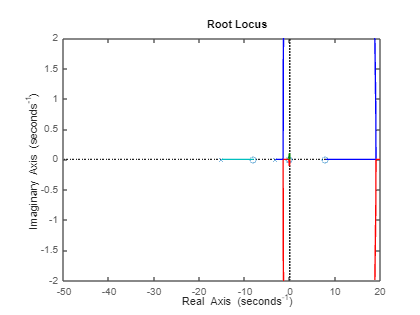

rlocus(C_phi*G_phi)
xlim([-50 20]), ylim([-2 2])

### **Diagrama de bode da malha fechada**

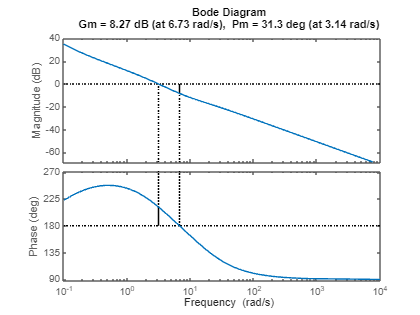

margin(k_phi*C_phi*G_phi)
xlim([1e-1 1e4])

### **Resposta ao degrau da planta em malha fechada**

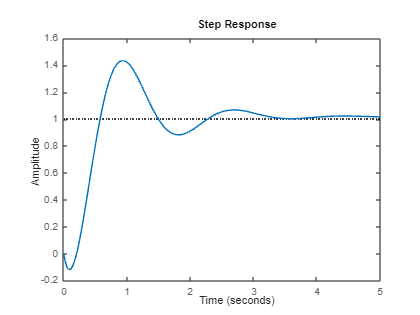

step(Gmf_phi)

## Sistema em malha fechada

Gmf = minreal(zpk(feedback(k_phi*C_phi*Gmf_theta*G_phi,1)))

Gmf =
 
                   -3711.4 (s+8.978) (s+7.961) (s+20) (s-7.961) (s+0.1)
  --------------------------------------------------------------------------------------
  (s+22.1) (s+0.1021) (s^2 + 2.24s + 20.64) (s^2 + 21.1s + 139.4) (s^2 + 41.66s + 650.3)
 
Continuous-time zero/pole/gain model.
Model Properties


### Resposta ao degrau do sistema em malha fechada

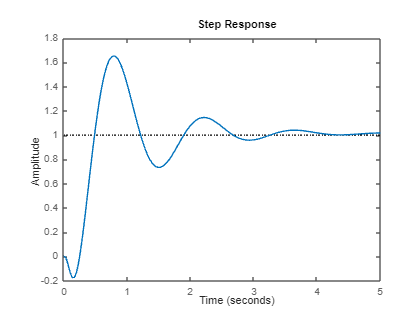

step(Gmf)

C_theta = tf(C_theta); k_theta * C_theta

ans =
 
  -72.98 s^2 - 2115 s - 1.31e04
  -----------------------------
          s^2 + 53.87 s
 
Continuous-time transfer function.
Model Properties


C_phi = tf(C_phi); k_phi * C_phi

ans =
 
   0.9994 s + 0.09994
  ---------------------
  s^2 + 18.14 s + 47.12
 
Continuous-time transfer function.
Model Properties


## Discretização

### Controlador de theta

zpk(k_theta*C_theta); C_theta_d = c2d(k_theta*C_theta, 0.005)

C_theta_d =
 
  -72.98 z^2 + 136.5 z - 63.84
  ----------------------------
     z^2 - 1.764 z + 0.7639
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


### Malha fechada de theta discretizado 

Gmf_theta_d = feedback(C_theta_d*c2d(G_theta,0.005), 1)

Gmf_theta_d =
 
     0.015501 (z+0.975) (z-0.9506) (z-0.9203) (z-1)
  -----------------------------------------------------
  (z-1) (z^2 - 1.855z + 0.8632) (z^2 - 1.823z + 0.8355)
 
Sample time: 0.005 seconds
Discrete-time zero/pole/gain model.
Model Properties


### Resposta ao degrau de theta discretizado

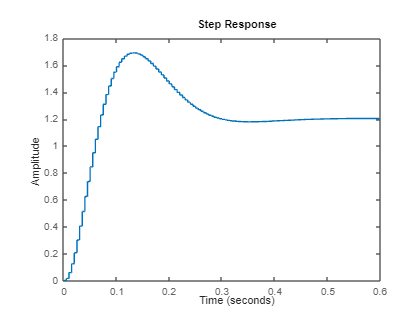

step(Gmf_theta_d)

Nc = C_theta_d.Numerator{1};
Dc = C_theta_d.Denominator{1};
M_theta = idpoly(Dc, Nc, 'NoiseVariance', 0)

M_theta =
Discrete-time ARX model: A(z)y(t) = B(z)u(t)
  A(z) = 1 - 1.764 z^-1 + 0.7639 z^-2       
                                            
  B(z) = -72.98 + 136.5 z^-1 - 63.84 z^-2   
                                            
Sample time: unspecified
  
Parameterization:
   Polynomial orders:   na=2   nb=3   nk=0
   Number of free coefficients: 5
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 
Model Properties


#### Ganhos do controlador de theta

M_theta.A, M_theta.B

ans =     1.0000   -1.7639    0.7639


ans =   -72.9757  136.5322  -63.8437


### Controlador de phi

zpk(k_phi*C_phi); C_phi_d = c2d(k_phi*C_phi, 0.005)

C_phi_d =
 
  0.004777 z - 0.004775
  ----------------------
  z^2 - 1.912 z + 0.9133
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


### Malha fechada de phi discretizado 

Gmf_d = feedback(C_phi_d*c2d(G_phi,0.005),1)

Gmf_d =
 
       -0.013954 (z-1) (z-0.9606) (z-1.04)
  ---------------------------------------------
  (z-0.9387) (z-0.9995) (z^2 - 1.988z + 0.9883)
 
Sample time: 0.005 seconds
Discrete-time zero/pole/gain model.
Model Properties


### Resposta ao degrau de phi discretizado

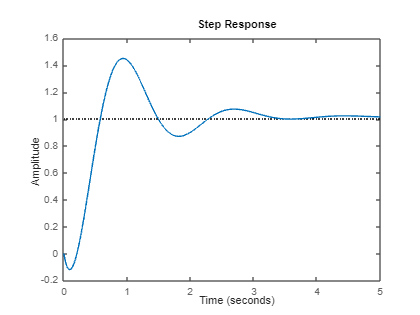

step(Gmf_d)

Nc = C_phi_d.Numerator{1};
Dc = C_phi_d.Denominator{1};
M_phi = idpoly(Dc, Nc, 'NoiseVariance', 0)

M_phi =
Discrete-time ARX model: A(z)y(t) = B(z)u(t)
  A(z) = 1 - 1.912 z^-1 + 0.9133 z^-2       
                                            
  B(z) = 0.004777 z^-1 - 0.004775 z^-2      
                                            
Sample time: unspecified
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=1
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 
Model Properties


#### Ganhos do controlador de phi

M_phi.A, M_phi.B

ans =     1.0000   -1.9122    0.9133


ans =          0    0.0048   -0.0048


## Funções de transferência dos controladores

zpk(k_theta*C_theta)

ans =
 
  -72.976 (s+20) (s+8.978)
  ------------------------
        s (s+53.87)
 
Continuous-time zero/pole/gain model.
Model Properties


zpk(k_phi*C_phi)

ans =
 
  0.99939 (s+0.1)
  ----------------
  (s+15) (s+3.142)
 
Continuous-time zero/pole/gain model.
Model Properties


## Ganhos discretizados dos controladores

M_theta.A, M_theta.B

ans =     1.0000   -1.7639    0.7639


ans =   -72.9757  136.5322  -63.8437


M_phi.A, M_phi.B

ans =     1.0000   -1.9122    0.9133


ans =          0    0.0048   -0.0048
